# Solve Differential Equation

With Matlab symbolic toolbox one can define symbolic differential algebraic equations to manipulate and eventually solve analytically the equations if possible.

The symbolic equations can also be converted to Matlab code (or also C code) to later solve them numerically.

## Solve Differential equations symbolically

by using `syms` to create the symbolic function `y(t)`.

syms y(t)

Define the equation using `==` and represent differentiation using the `diff` function.

ode = diff(y,t) == t*y

$$ode(t) = \frac{\partial }{\partial t}y\left(t\right)=t\,y\left(t\right)$$

Solve the equation using `dsolve`.

ySol(t) = dsolve(ode)

$$ySol(t) = C_{1}\,{\mathrm{e}}^{\frac{t^{2}}{2}}$$

#### **Solve Differential Equation with Condition**

In the previous solution, the constant appears because no condition was specified. Solve the equation with the initial condition `y(0) == 2`. The `dsolve` function finds a value of that satisfies the condition.

cond = y(0) == 2;
ySol(t) = dsolve(ode,cond)

$$ySol(t) = 2\,{\mathrm{e}}^{\frac{t^{2}}{2}}$$

We can then plot the solution

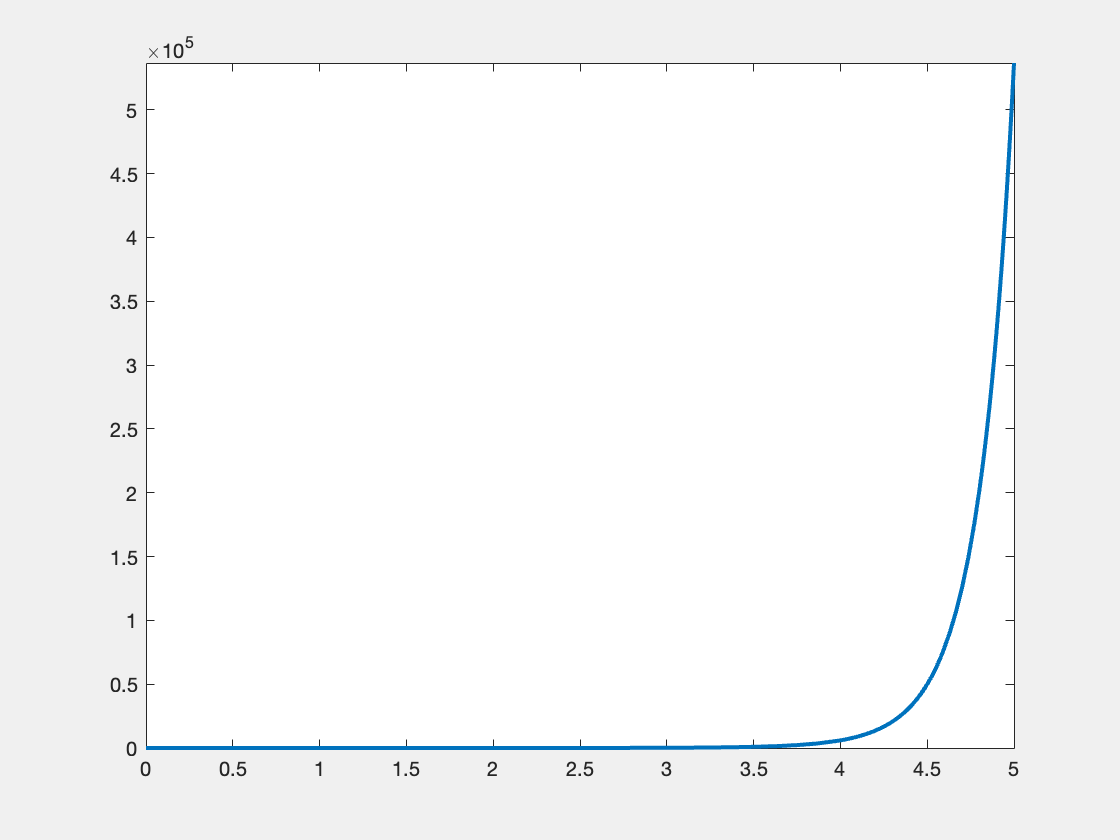

fplot(ySol(t),[0,5],'Linewidth',2)

## Solve Differential Equation Numerically

If `dsolve` cannot solve our equation, we can try solving the equation numerically. 

syms y(t);
eqn = diff(y(t),t,2) == (1-y(t)^2)*diff(y(t),t) - y(t)

$$eqn = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=-\left({y\left(t\right)}^{2}-1\right)\,\frac{\partial }{\partial t}y\left(t\right)-y\left(t\right)$$

Use `reduceDifferentialOrder` to rewrite that equation as a system of two first-order differential equations. Here, `vars` is a vector of state variables of the system. The new variable `Dy(t)` represents the first derivative of `y(t)` with respect to `t`.

[eqs,vars] = reduceDifferentialOrder(eqn,y(t))

$$eqs = \left(\begin{array}{c} \frac{\partial }{\partial t}\mathrm{Dyt}\left(t\right)+y\left(t\right)+\mathrm{Dyt}\left(t\right)\,\left({y\left(t\right)}^{2}-1\right)\\ \mathrm{Dyt}\left(t\right)-\frac{\partial }{\partial t}y\left(t\right) \end{array}\right)$$

$$vars = \left(\begin{array}{c} y\left(t\right)\\ \mathrm{Dyt}\left(t\right) \end{array}\right)$$

Set initial conditions for `y(t)` and its derivative `Dy(t)` to `2` and `0` respectively

initConditions = [2 0];

.Find the mass matrix `M` of the system and the right sides of the equations `F` and write the system in explicit form

[M,F] = massMatrixForm(eqs,vars)

$$M = \left(\begin{array}{cc} 0 & 1\\ -1 & 0 \end{array}\right)$$

$$F = \left(\begin{array}{c} -y\left(t\right)-\mathrm{Dyt}\left(t\right)\,\left({y\left(t\right)}^{2}-1\right)\\ -\mathrm{Dyt}\left(t\right) \end{array}\right)$$

f = M\F

$$f = \left(\begin{array}{c} \mathrm{Dyt}\left(t\right)\\ -\mathrm{Dyt}\left(t\right)\,{y\left(t\right)}^{2}-y\left(t\right)+\mathrm{Dyt}\left(t\right) \end{array}\right)$$

#### Generate MATLAB function with `odeFunction`

Convert `f` to a MATLAB function handle by using `odeFunction`. The resulting function handle is input to the MATLAB ODE solver `ode15s`.

odefun = odeFunction(f,vars)

odefun = function_handle with value:
    @(t,in2)[in2(2,:);in2(2,:)-in2(1,:)-in2(2,:).*in2(1,:).^2]


Then it can be solved numerically with one of Matlab solver:

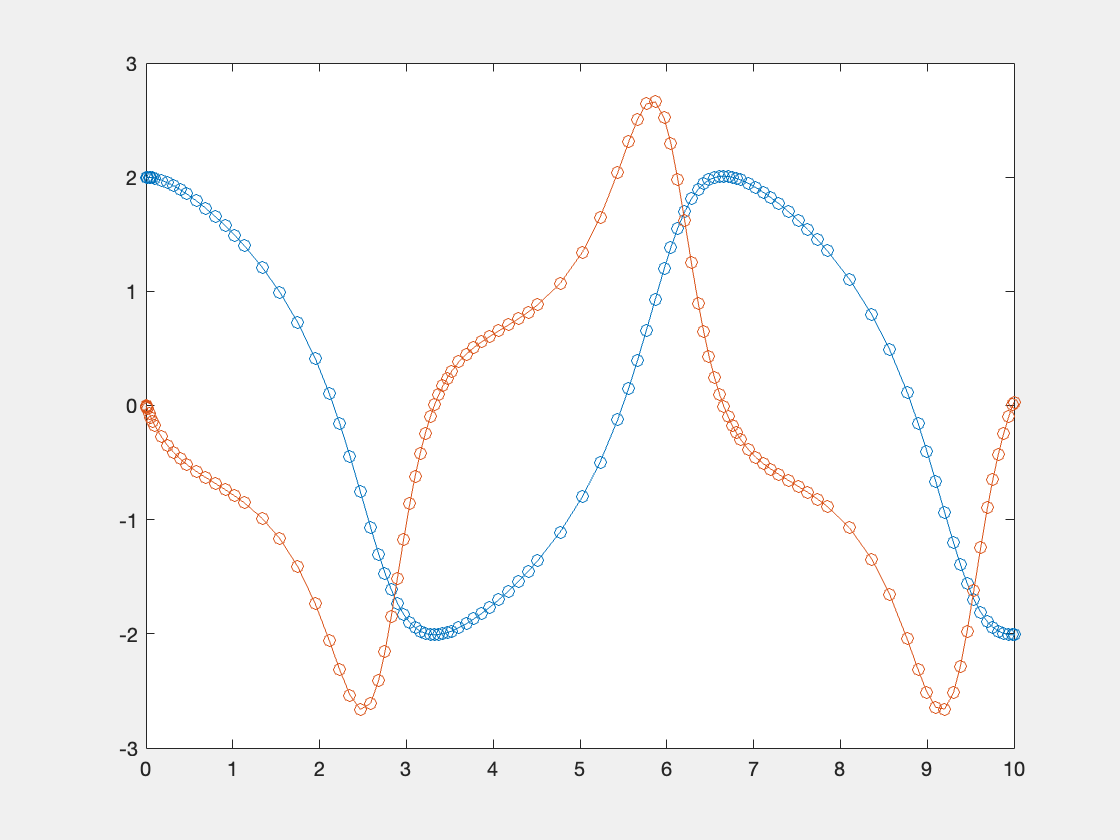

ode15s(odefun, [0 10], initConditions)

**Generate MATLAB Function with **`matlabFunction`

The MATLAB ODE solvers do not accept symbolic expressions as an input. Therefore, before one can use a MATLAB ODE solver to solve the system, the system must be converted to a MATLAB function. 

syms y(t);
ode = diff(y,2) + diff(y)/2 + 2*y == 0

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+\frac{\frac{\partial }{\partial t}y\left(t\right)}{2}+2\,y\left(t\right)=0$$

First of all to solve the differential equation, convert it to **first-order** differential equations by using the `odeToVectorField` function. The command reduces the order of the differential system adding the dummy variables and return the system as a vector of symbolic equations.

V = odeToVectorField(ode)

$$V = \left(\begin{array}{c} Y_{2}\\ -2\,Y_{1}-\frac{Y_{2}}{2} \end{array}\right)$$


% One can also reduce the system to an ode directly with
% reduceDifferentialOrder() and then convert it to a vectorfield
%V = odeToVectorField(eqs)

Next, convert the symbolic expression `V` to a MATLAB function file by using [`matlabFunction`](https://it.mathworks.com/help/symbolic/sym.matlabfunction.html). The converted function in the file `myODE.m` can be used without Symbolic Math Toolbox™. The converted function is deployable with MATLAB Compiler.

% write the matlab function to a file with name myODE
M = matlabFunction(V,'vars',{'t','Y'},'File','myODE')

M = function_handle with value:
    @myODE


%my_fun = matlabFunction(V,'vars',{'t','Y'})

It can now be solved numerically

sol = ode45(@myODE,[0 20],initConditions)

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 5.0238e-05 3.0143e-04 0.0016 0.0078 0.0392 0.1962 0.6849 1.2846 1.8306 2.3835 2.9014 3.4799 4.0334 4.5708 5.1002 5.6596 6.2234 6.7418 7.2840 7.8215 8.3976 8.8922 9.4490 9.9597 10.5512 11.0441 11.6182 12.1021 12.7084 … ] (1×44 double)
          y: [2×44 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


%sol = ode45(@my_fun,[0 20],initConditions)

Then we can plot the solution

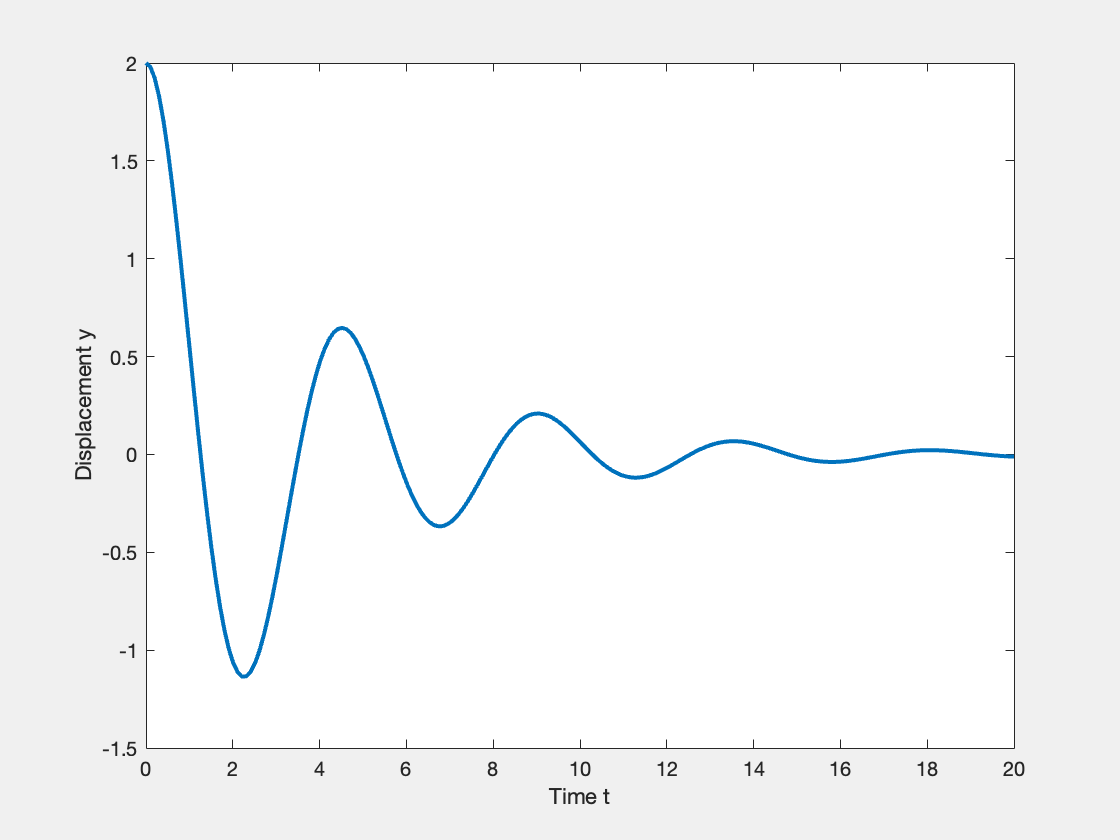

x = linspace(0,20,200);
% with command deval() we evaluate differential equation solution structure
% over the values of x and for the component 1
y = deval(sol,x,1);
plot(x,y,'Linewidth',2)
xlabel('Time t')
ylabel('Displacement y')

## ODE with parameters

% x(t) v(t) are the state variables
% f(t) is a function of time
% m k c are constant parameters
clear ;

syms x(t) v(t) m k c f(t);

ode = [ diff(x(t),t) == v(t), ...
        m*diff(v(t),t)+c*v(t)+k*x(t) == f(t)];
vars = [x(t) v(t)];

Find mass matrix

[M,F] = massMatrixForm(ode,vars)

$$M = \left(\begin{array}{cc} 1 & 0\\ 0 & m \end{array}\right)$$

$$F = \left(\begin{array}{c} v\left(t\right)\\ f\left(t\right)-c\,v\left(t\right)-k\,x\left(t\right) \end{array}\right)$$

Generate Matlab function 

M = odeFunction(M,vars,m)

M = function_handle with value:
    @(t,in2,param29)reshape([1.0,0.0,0.0,param29],[2,2])


F = odeFunction(F,vars,k,c,f(t))

F = function_handle with value:
    @(t,in2,param30,param31,param32)[in2(2,:);param32-param31.*in2(2,:)-param30.*in2(1,:)]


Numerically solve the ode

Specify the parameters

m = 10;
c = 5;
k = 100;
%f = @(t) 0; %cos(t);
f = @(t) cos(t);

%Create the reduced function handle F.
F = @(t,Y) F(t,Y,k,c,f(t));
M = @(t,Y) M(t,Y,m);

Specify consistent initial conditions for the ode system

initConditions = [0.1 0];

Create an option set that contains the mass matrix `M` of the system

opt = odeset('mass',M)

opt = struct with fields:
              AbsTol: []
                 BDF: []
              Events: []
         InitialStep: []
            Jacobian: []
           JConstant: []
            JPattern: []
                Mass: @(t,Y)M(t,Y,m)
        MassSingular: []
            MaxOrder: []
             MaxStep: []
             MinStep: []
         NonNegative: []
         NormControl: []
           OutputFcn: []
           OutputSel: []
              Refine: []
              RelTol: []
               Stats: []
          Vectorized: []
    MStateDependence: []
           MvPattern: []
        InitialSlope: []


Solve numerically

sol = ode45(F,[0 20],initConditions, opt)

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 2.2328e-04 0.0013 0.0069 0.0348 0.1744 0.4063 0.6754 0.9042 1.1631 1.3852 1.6503 1.8679 2.1265 2.3510 2.6163 2.8465 3.1151 3.3416 3.6014 3.8573 4.0958 4.3229 4.5752 4.7987 5.0484 5.2737 5.5320 5.7639 6.0312 6.2835 6.5304 … ] (1×82 double)
          y: [2×82 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


Plot solution

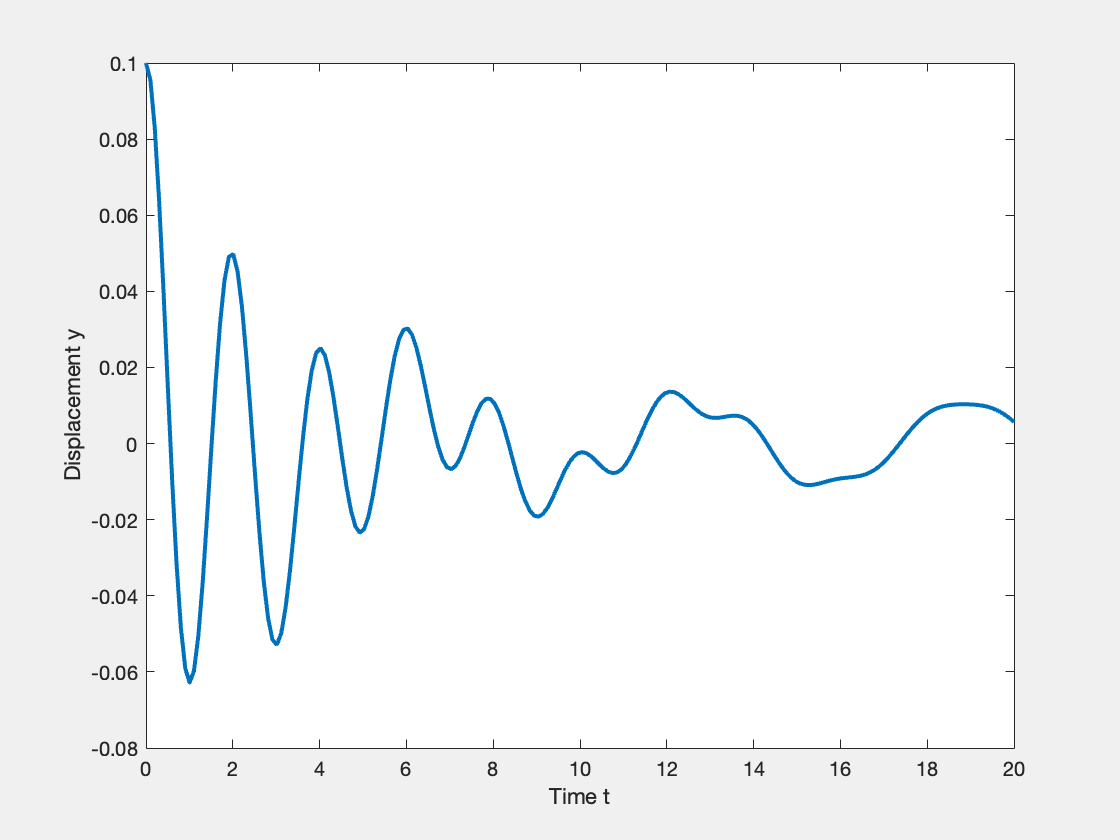

tt = linspace(0,20,200);
% with command deval() we evaluate differential equation solution structure
% over the values of x and for the component 1
x_def = deval(sol,tt,1);
plot(tt,x_def,'Linewidth',2)
xlabel('Time t')
ylabel('Displacement y')